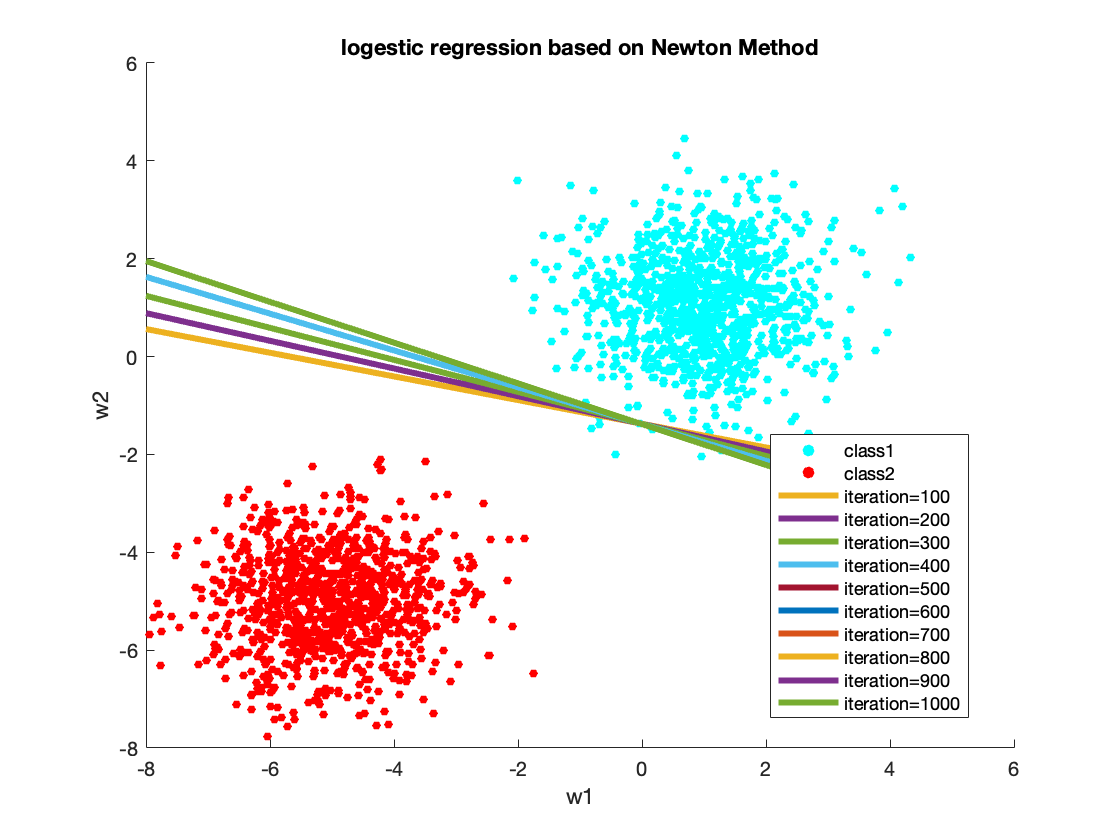

close all
clear 

% logestic regression based on Newton Method demo

% define sigmoid function
sig_fun = @(x) 1 ./ (1+exp(-x));

% specify sample amount, feature dimension, mean and covariance
k = 1000;
dimension = 2;
mu1 = [1;1];
co1 = [1 0; 0 1];
mu2 = [-5;-5];
co2 = [1 0; 0 1];
rng(1)
X1 = generate_gassian_data(k, dimension, mu1, co1);
X2 = generate_gassian_data(k, dimension, mu2, co2);
y1 = ones([k,1]);
y2 = zeros([k,1]);
X = [X1, X2];
X = [X; ones([1,2*k])];
y = [y1; y2]';

% initial weight
weight = [-1; -3; 1];
x_range = -8:1:4;
figure;
% scatter two gaussian class
scatter(X1(1,:), X1(2,:), ...
    'filled', "MarkerFaceColor",'c', "SizeData",20, 'DisplayName', 'class1')
hold on
scatter(X2(1,:), X2(2,:), ...
    'filled', "MarkerFaceColor",'r', "SizeData",20, 'DisplayName', 'class2')
% optimization iteration 1000
for i=1:1000
    z = weight'*X;
    p = sig_fun(z);
    if rem(i, 100)==0
        txt = ['iteration=',num2str(i)];
        plot(x_range, (-weight(3) - weight(1).*x_range)./weight(2), ...
            "LineWidth", 3, "DisplayName",txt)
    end
    loss = sum(y.*log2(p) + (1-y).*log2(1-p))/200;
    grad = X*(y'-p');
    hessian = -X*p'.*(1-p)*X';
    weight = weight - pinv(hessian)*grad;
end
xlabel('w1')
ylabel('w2')
title('logestic regression based on Newton Method')
legend("Location","best")
hold off